# Benchmarking Forecasting Methodologies

The existing comparisons during COVID-19 are those of forecasts (forecasting teams) rather than forecasting methodologies. Instead of "who did well", we are interested in "what worked well" over the duration of the pandemic

The goal of this work is to compare various methodologies and create a benchmark against which new methodologies can be evaluated. When designing a new methodology, bringing the entire evaluation to one error number is not enough. One has to assess the performance over time, and the difficulty of forecasting is likely to be different over the period. The benchmark, as the performances of collection of methodologies over time, can guide in a better assessment.

This work will also identify various decisions that affect the accuracy of forecasts from the submit methodologies. These "decisions" may include:

- Modeling technique: Generative (SIR, SEIR, ...), Discriminative (Neural Networks, ARIMA, ...), ...

- Learning approach: Bayesian, Regression (Quadratic Programming, Gradient Descent, ...), ...

- Pre-processing: Smoothing (1 week, 2, week, auto), anomaly detection, ...

## Data for evaluation

We use the latest JHU data as the ground truth. Note that this in not to be used for training. 

Forecasts on a past date must use the data that was available that day for training. The versions of JHU data available on various days of the past are available as timeseries in: [https://github.com/scc-usc/ReCOVER-COVID-19/blob/master/results/historical_forecasts](https://github.com/scc-usc/ReCOVER-COVID-19/blob/master/results/historical_forecasts)

clc, clear all, close all
warning off;
addpath('./hyper_params/');
load_data_us;

## List of methods already included

The current files are derived from: [https://github.com/reichlab/covid19-forecast-hub/tree/master/data-processed](https://github.com/reichlab/covid19-forecast-hub/tree/master/data-processed)

As described earlier, we would like to switch to methodologies. We invite the interested teams to submit forecasts generated by their methodology using the historical versions of JHU data at: [https://github.com/scc-usc/ReCOVER-COVID-19/blob/master/results/historical_forecasts](https://github.com/scc-usc/ReCOVER-COVID-19/blob/master/results/historical_forecasts)

Please note that any change in your approach, including data pre-processing and hand-tuning a parameter counts as a different methodology. The instructions for submitting your forecasts to us are available at: [https://github.com/scc-usc/covid19-forecast-bench](https://github.com/scc-usc/covid19-forecast-bench)


lastday = size(deaths, 2)-1; 
firstday = 120;
skipdays = 7;

time_stamps =(firstday:lastday);
defpath = '../results/others_death_forecasts/biweekly_reports/';
data_src = {'JHU'}; % Next we list methods that use these data sources in order
%method_list{1} = {'LANL_GrowthRate'; 'YYG_ParamSearch'; 'CU_select'; 'SIkJa_smooth7_un10'; 'SIkJa_smooth14_un10'; 'SIkJa_window_noval'; 'SIkJa_USC'};
xx = cellstr(ls([defpath '/*.csv']));
yy = unique(cellfun(@(x)(x(1:end-8)), xx, 'UniformOutput', false));
methods = [yy; 'SIkJa_USC'; 'ensemble_SIkJa'];

skip_idx = contains(methods, 'un20');
methods(skip_idx) = [];

## Loading other forecasts

Assumes that all the submissions are pre-processes and stored in "../results/others_death_forecasts/biweekly_reports/"

Change this directory appropriately. Could be swithced to the the state-deaths and state-cases directories in the forecast bench


a_sunday = 94;
for mm = 1:length(methods)
    num_files = 0;
    for tt = 1:length(time_stamps)
        if (contains(methods{mm}, 'SIk')|| contains(methods{mm}, 'YYG')) && mod(time_stamps(tt) - a_sunday, 7)~=0
            continue;
            % Only loading Sunday forecasts here. The above methods have
            % other days available too which are ignored here.
        end
        try
            fname = [methods{mm}, '_', num2str(time_stamps(tt)+1), '.csv'];
            preds = readtable(['../results/others_death_forecasts/biweekly_reports/', fname]);
            preds = preds{1:end, 3:end};
            preds(1, 1) = preds(1, 1) - 1; % Correcting the discrepancy in date labeling
            eval([methods{mm}, '{',  num2str(tt),'} = ', 'preds;']);
            num_files = num_files + 1;
        catch
            eval([methods{mm}, '{',  num2str(tt),'} = ', '-1;']);
        end
    end
    disp(['Loaded' num2str(num_files) ' for ', methods{mm}]);
end

Loaded24 for SIkJa_smooth14_un10_hyper7
Loaded24 for SIkJa_smooth7_un10_hyper7
Loaded24 for SIkJa_window_noval
Loaded19 for USC_SI_kJalpha_state_death
Loaded16 for YYG_ParamSearch
Loaded18 for reich_COVIDhub_ensemble_state_death
Loaded16 for reich_LNQ_ens1_state_death
Loaded18 for reich_OliverWyman_Navigator_state_death
Loaded15 for reich_SteveMcConnell_CovidComplete_state_death
Loaded18 for reich_UCLA_SuEIR_state_death
Loaded0 for SIkJa_USC
Loaded0 for ensemble_SIkJa


## Forecasts from our methodology (one version)

Forecasts generated by the current verison of our methodology are available in [https://github.com/scc-usc/ReCOVER-COVID-19/blob/master/results/historical_forecasts](https://github.com/scc-usc/ReCOVER-COVID-19/blob/master/results/historical_forecasts)

In the future, more versions will be added to be compared as separate methodologies. Note that, any change, including simply changing the smoothing factor is also considered to be a different methodology. 

% Our results are generated in daily format. 
% So we convert them to the common format for evaluation as described before.

a_sunday = 94; % We will use this to identify which other columns should be Sundays
for tt = 1:length(time_stamps)-1 % Pick some days and generate forecasts
    if mod(time_stamps(tt) - a_sunday, 7)~=0
        SIkJa_USC{tt} = -1;
        continue;
    end
    
    forecast_date = datetime(2020, 1, 24)+caldays(time_stamps(tt));
    path = '../results/historical_forecasts/';
    dirname = datestr(forecast_date, 'yyyy-mm-dd');
    fullpath = [path dirname];
    
    dtab = readtable([fullpath '/' prefix '_forecasts_deaths.csv']);
    death_pred = dtab{2:end, 4:end};
    base_deaths1 = dtab{2:end, 3};  % deaths observed in the day of forecasts
    dcols = time_stamps(tt)+1:(time_stamps(tt)+(size(death_pred, 2)));
    try
        dow = mod(tt-a_sunday, 7) + 1;
        if  dow == 1 || dow == 2 %If the sunday before has been observed, use the observed as base deaths
            base_deaths = deaths(:, time_stamps(tt) - dow + 1);
            first_pred_sunday = time_stamps(tt) - dow + 1+ 7;
        else
            base_idx = find(dcols == (time_stamps(tt)+8-dow));
            base_deaths = death_pred(:, base_idx(1));
            first_pred_sunday = time_stamps(tt) + 8 - dow + 7;
        end
    catch
        continue;
    end
    
    first_sunday_idx = find(dcols==first_pred_sunday);
    sun_cols = dcols(first_sunday_idx(1):7:end);
    
    weekly_preds = [base_deaths1, diff([base_deaths death_pred(:, first_sunday_idx(1):7:end)]')'];
    SIkJa_USC{tt} = [[time_stamps(tt) sun_cols]; weekly_preds];
    fprintf('.');
end

.........................

## Train Ensemble of SIkJa

%inc_methods = methods(startsWith(methods, 'SIkJa_s')| startsWith(methods, 'SIkJa_w'));
inc_methods = methods([1 2 3]);
a_sunday = 94;
num_rows = 57; num_cols = 5;
xx = zeros(num_rows, num_cols, length(inc_methods));
for tt = 1:length(time_stamps)
    for mm = 1:length(inc_methods)
        try
            pred_files = eval([inc_methods{mm} '{' num2str(tt) '}']);
            xx(:, :, mm) = pred_files(:, 1:num_cols);
        catch
            xx(:, :, mm) = zeros(num_rows, num_cols);
        end
    end
        SIkJa_ensemble{tt} = -1;
        weak_learners{tt} = xx;
end

min_tt = 14;
train_tt = 1+min_tt+ (num_cols-1)*7;

Xdata = cell(4, 1); Ydata = cell(4, 1);
for tt=1:train_tt
    if mod(time_stamps(tt) - a_sunday, 7)~=0
        ensemble_SIkJa{tt} = -1;
        continue;
    end
    
    for jj=1:4
        
        if tt-7*jj <= 0 % Ground truth not available for trianing
            continue;
        end
        
        xx = weak_learners{tt-7*jj};
        %% Additional features
        this_inc = deaths(:, time_stamps(tt)-7*jj) - deaths(:, time_stamps(tt)-7*(jj+1));
        prev_inc = deaths(:, time_stamps(tt)-7*(jj+1)) - deaths(:, time_stamps(tt)-7*(jj+2));
        extern_dat = [deaths(:, time_stamps(tt)-7*jj), this_inc, prev_inc, jj*ones(length(this_inc), 1)]; %, (1:num_rows-1)'];
        
        xx = [squeeze(xx(2:end , jj+1, 1:end)) extern_dat];
        yy = deaths(:, time_stamps(tt)) - deaths(:, time_stamps(tt) - 7);
        Xdata{jj} = [Xdata{jj}; xx];
        Ydata{jj} = [Ydata{jj}; yy];
    end
    ensemble_SIkJa{tt} = -1;
end

for tt = train_tt+1:length(time_stamps)
    if mod(time_stamps(tt) - a_sunday, 7)~=0
        ensemble_SIkJa{tt} = -1;
        continue;
    end
    
    xx = weak_learners{tt};
    preds = zeros(num_rows, num_cols);
    preds(:, 1) = squeeze(xx(1:end, 1, 1));
    preds(1, 2:end) = squeeze(xx(1, 2:end, 1));
    
    % Train with the data so far and predict
    mdl = TreeBagger(40, [Xdata{1}; Xdata{2}; Xdata{3}; Xdata{4}], [Ydata{1}; Ydata{2}; Ydata{3}; Ydata{4}], 'Method','regression', 'CategoricalPredictors',[size(Xdata{1}, 2)]);
    for jj=1:num_cols-1
        %% Additional features
        this_inc = deaths(:, time_stamps(tt)) - deaths(:, time_stamps(tt)-7);
        prev_inc = deaths(:, time_stamps(tt)-7) - deaths(:, time_stamps(tt)-14);
        extern_dat = [deaths(:, time_stamps(tt)), this_inc, prev_inc, jj*ones(length(this_inc), 1)]; %, (1:num_rows-1)'];

        thisxx = [squeeze(xx(2:end, jj+1, 1:end)) extern_dat];     
        %preds(2:end, jj+1) =  quantilePredict(Mdl{jj},thisxx,'Quantile',[0.5]);
        preds(2:end, jj+1) =  predict(mdl,thisxx);
    end
    ensemble_SIkJa{tt} = preds;
    fprintf('.');
    % Add data to the next training
    for jj=1:num_cols-1
        try
            xx = weak_learners{tt-7*jj};
            %% Additional features
            this_inc = deaths(:, time_stamps(tt)-7*jj) - deaths(:, time_stamps(tt)-7*(jj+1));
            prev_inc = deaths(:, time_stamps(tt)-7*(jj+1)) - deaths(:, time_stamps(tt)-7*(jj+2));
            extern_dat = [deaths(:, time_stamps(tt)-7*jj), this_inc, prev_inc, jj*ones(length(this_inc), 1)]; %, (1:num_rows-1)'];
            
            xx = [squeeze(xx(2:end, jj+1, 1:end)) extern_dat];
            yy = deaths(:, time_stamps(tt)) - deaths(:, time_stamps(tt)-7);
            Xdata{jj} = [Xdata{jj}; xx]; Xdata{jj}(1:num_rows-1, :) = [];
            Ydata{jj} = [Ydata{jj}; yy]; Ydata{jj}(1:num_rows-1, :) = [];
        catch
            continue;
        end
    end
end

...................

## Error matrices

We generate a matrix where element (i, j) represents the error of forecast generated on day i for week j. The forecasts are expected to be incident cases forecasts per week. We do not compute the errors for a week when the forecast was performed on a day after Monday of the same week. This is in accordance with the forecasting hub.

first_tt = 1;
cidx = popu > -1;
a_sunday = 94;
cidx([51, 52, 53, 55, 56]) = 0; % Others do not forecast for these states
all_sundays = (firstday+7-mod(firstday-a_sunday, 7)):7:size(deaths, 2); % All sundays in the data
sun_map = containers.Map(all_sundays, 1:length(all_sundays));

sunday_gt  = [(a_sunday+7:7:size(deaths, 2));diff(deaths(:, a_sunday:7:end)')'];
for mm = 1:length(methods)
    err_mat = nan(lastday-firstday+1, length(all_sundays));
    err_mat1 = err_mat;
    for tt=first_tt:length(time_stamps)
        if (contains(methods{mm}, 'SIk')|| contains(methods{mm}, 'YYG')) && mod(time_stamps(tt) - a_sunday, 7)~=0
            continue;
        end
    
        try
        pred_files = eval([methods{mm} '{' num2str(tt) '}']);
        catch
            continue;
        end
        if length(pred_files) <= 1
            continue;
        end
        rem_idx = pred_files(1, :) > size(deaths, 2); % If the data has not been observed, remove the prediction
        pred_files(:, rem_idx) = [];
        pred_dates = pred_files(1, 2:end);
        
        if length(pred_dates) < 1 % This means only the base deaths are left, no forecast to evaluate
            continue;
        end
        
        if any(diff(pred_dates) ~= 7) && length(pred_dates)>1
            continue;
        end
        
        gt_start = find(sunday_gt(1, :) == pred_dates(1)); % sundays on or after predicted days
        
        if length(gt_start)<1
            continue;
        end
        
        gt = sunday_gt(logical([0; cidx]), int32(gt_start(1):1:gt_start(1)+length(pred_dates)-1));
        preds = pred_files(2:end, 2:end);
        preds = (preds(cidx, :) + abs(preds(cidx, :)))/2;
        err_vec = nanmean(2*abs(gt-preds)./abs(gt+preds), 1);
        err_vec1 = nanmean(abs(gt-preds), 1);
        if any(isinf(err_vec))
            fprintf('.');
        end
        
        mapped_vec = arrayfun(@(x)sun_map(x), pred_dates);
        err_mat(tt, mapped_vec) = err_vec;
        err_mat1(tt, mapped_vec) = err_vec1;
    end
    eval(['SMAPE_' methods{mm}  '= err_mat;']);
    eval(['MAE_' methods{mm}  '= err_mat1;']);
end


## x-week-ahead forecast errors

On a given date, 1-week-ahead is the incident forecast for the week ending on that week if the forecast is performed on a Sunday or a Monday, and the next week if the forecast is performed on other days of the week. This is in accordance with Reich Lab forecast submissions. Same rule is used for 2-, 3-, 4-week ahead calculations

first_tt = 164-time_stamps(1);
for mm=1:length(methods)
    err_mat1 = eval(['MAE_' methods{mm}]);
    tot_ahead = 4;
    ahead_error = nan(tot_ahead, size(err_mat1, 1));
    for aidx = 1:tot_ahead
        for tt=first_tt:length(time_stamps)
            sun_lb = time_stamps(tt) + aidx*7 - 1;
            sun_ub = time_stamps(tt) + aidx*7 + 5;
            sun_idx = find(all_sundays >= sun_lb & all_sundays <= sun_ub);
            
            if ~isempty(sun_idx)
               ahead_error(aidx, tt) = err_mat1(tt, sun_idx(1)); 
            end
        end
    end
    eval(['ahead_error_' methods{mm} ' = ahead_error;']);
end


## 4-week-ahead plots

Errors for x-week ahead for a forecast made from data available on the "date of release".

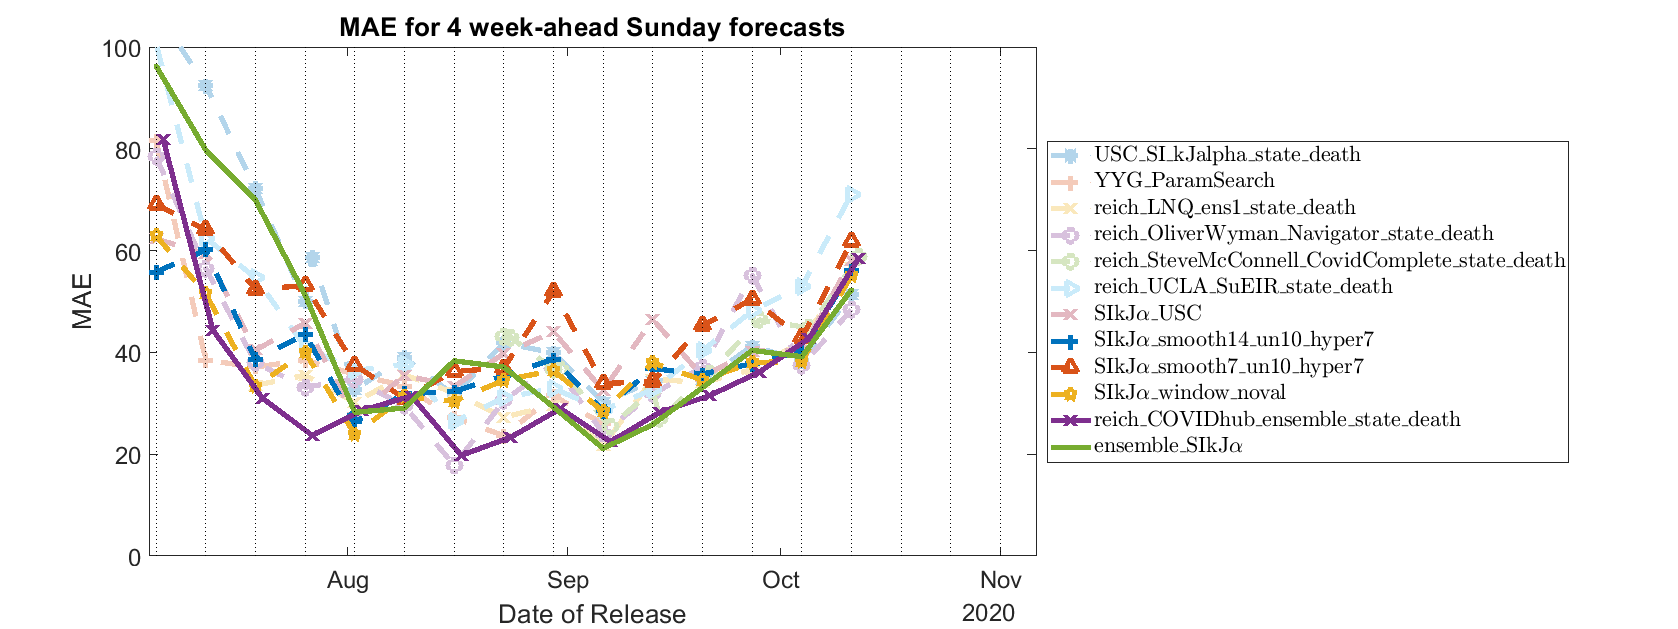

highlight_idx = 0.3*ones(length(methods), 1);
highlight_idx([1 2 3 6 12]) = 1;
hard_line = zeros(length(methods), 1); 
hard_line([6 12]) = 1;

all_marks = {'o','+','*','.','x','s','d','^','v','>','<','p','h'};
reorder_idx = [find(highlight_idx<1); find(highlight_idx==1)];
for aidx = 4
    figure('DefaultAxesFontSize',18);
    set(gcf,'position',[10,10,2000,750]);
    ll = {};
    for mm1=1:length(methods)
        mm = reorder_idx(mm1);
        eval(['ahead_error = ahead_error_' methods{mm} ';']);
        errs = ahead_error(aidx, :);
        nnanidx = ~isnan(errs);
        Tx = datetime(2020, 1, 23)+ caldays(time_stamps);
        if hard_line(mm) == 1
            lstyle = '-';
        else
            lstyle = '--';
        end
        p1 = plot(Tx(nnanidx), errs(nnanidx), 'Marker', all_marks{randi(13, 1)}, 'LineStyle', lstyle, 'LineWidth', 4, 'MarkerSize', 10);
        try
        p1.Color  = 1 - highlight_idx(mm).*(1-p1.Color);
        catch
            continue;
        end
        hold on;
        ll = [ll; methods{mm}];
    end
    xlim([datetime(datetime(2020, 1, 23)+ caldays(time_stamps(first_tt))), datetime(2020, 1, 23)+ caldays(lastday-7)]);
    title(['MAE for ' num2str(aidx) ' week-ahead Sunday forecasts']);
    xlabel('Date of Release');
    ylabel('MAE');
    ylim([0, 100]);
    
    g_x = datetime(2020, 1, 23)+ caldays(all_sundays);
    %xticks(sundates);
    for i=1:length(g_x)
        plot([g_x(i) g_x(i)],[0 120],'k:') %x grid lines
        hold on
    end
    hold off;
    ll = strrep(ll, '_', '\_');
    ll = strrep(ll, 'SIkJa', 'SIkJ$\alpha$');
    %legend(ll, "Interpreter","latex", 'location', 'eastoutside');
    legend(ll, "Interpreter","latex", 'location', 'eastoutside');
end